# Introduction to MatNWB

**Goal:** In this tutorial we will create and save an NWB file that holds metadata and data from a fictional session in which a mouse searches for cookie crumbs in an open arena. At the end we will read the file back for a quick inspection.

## Installing MatNWB

If you don't have MatNWB already, let's clone it from GitHub and install into your current working directory (NB: requires git). 

if ~exist('NwbFile', 'class') % Skip if MatNWB is already on path
    !git clone https://github.com/NeurodataWithoutBorders/matnwb.git
    addpath(genpath('matnwb'));
    disp('Success! Cloned MatNWB from Github and added to MATLAB''s search path.')
end

## Set up the NWB File

An NWB file must have a unique `identifier`, a `session_description`, and a `session_start_time`. Let’s start by creating a new [`NwbFile`](https://matnwb.readthedocs.io/en/latest/pages/functions/NwbFile.html) object and assigning values to those required fields as well as some recommended metadata fields:

nwb = NwbFile( ...
    'identifier', 'MyLab_20250411_1530_AL', ... % Unique ID
    'session_description', 'Mouse searching for cookie crumbs in an open arena', ...
    'session_start_time', datetime(2025,4,11,15,30,0, 'TimeZone', 'local'), ...
    'general_experimenter', 'Doe, Jane', ... % optional
    'general_session_id', 'session_001', ... % optional
    'general_institution', 'Dept. of Neurobiology, Cookie Institute', ... % optional
    'general_related_publications', {'DOI:10.1016/j.neuron.2016.12.011'}); % optional

% Display the nwb object
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.9.0'
                                        file_create_date: []
                                              identifier: 'MyLab_20250411_1530_AL'
                                     session_description: 'Mouse searching for cookie crumbs in an open arena'
                                      session_start_time: {[2025-04-11T15:30:00.000000+02:00]}
                               timestamps_reference_time: []
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: ''
                                         general_devices: [0×1 types.untyped.Set]
                                  ge

Great! You now have an in-memory [`NwbFile`](https://matnwb.readthedocs.io/en/latest/pages/functions/NwbFile.html) object with all the required metadata. In the following sections, we will populate the file with additional metadata and data from our fictional session.

**Tip: See the **[**NWBFile Best Practices**](https://nwbinspector.readthedocs.io/en/dev/best_practices/nwbfile_metadata.html#file-metadata)** for detailed recommendations of which metadata to add to the **[`NwbFile`](https://matnwb.readthedocs.io/en/latest/pages/functions/NwbFile.html)

## Add Subject Metadata

First we will describe the mouse that took part in this session using the [`Subject`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Subject.html) class.

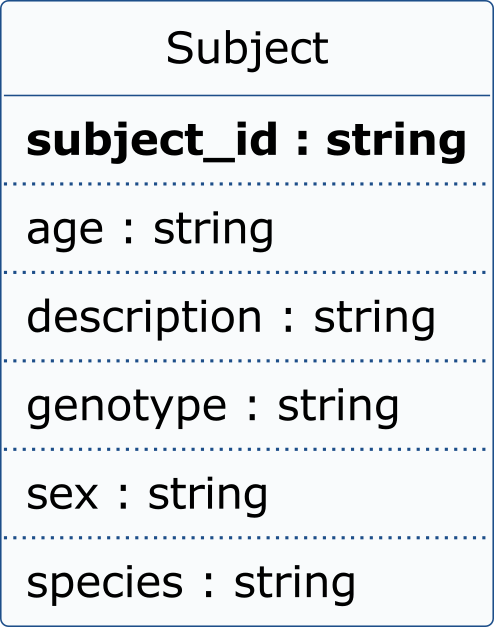  

All of these fields accept free-form text, so any value is technically valid, but we will follow the [**Best Practices**](https://nwbinspector.readthedocs.io/en/dev/best_practices/nwbfile_metadata.html#subject) recommendations:

- **age** – use an [**ISO 8601 Duration format**](https://en.wikipedia.org/wiki/ISO_8601#Durations), e.g. `P90D` for post-natal day 90

- **species** – give the **Latin binomial**, e.g. `Mus musculus`, `Homo sapiens`

- **sex** – use a single letter: **F** (female), **M** (male), **U** (unknown), or **O** (other)

subject = types.core.Subject( ...
    'subject_id', 'MQ01', ...        % Unique animal ID
    'description', 'Meet Monty Q., our cookie-loving mouse.', ...
    'age', 'P90D', ...              % ISO-8601 duration (post-natal day 90)
    'species', 'Mus musculus', ...  % Latin binomial
    'sex', 'M' ...                  % F | M | U | O
);

nwb.general_subject = subject;      % Subject goes into the `general_subject` property
disp(nwb.general_subject)           % Confirm the subject is now part of the file

  Subject with properties:

              age: 'P90D'
    age_reference: 'birth'
    date_of_birth: []
      description: 'Meet Monty Q., our cookie-loving mouse.'
         genotype: ''
              sex: 'M'
          species: 'Mus musculus'
           strain: ''
       subject_id: 'MQ01'
           weight: ''



## Add TimeSeries Data

Many experiments generate signals sampled over time and in NWB you store those signals in a [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html) object. The diagram below highlights the key fields of the [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html) class.

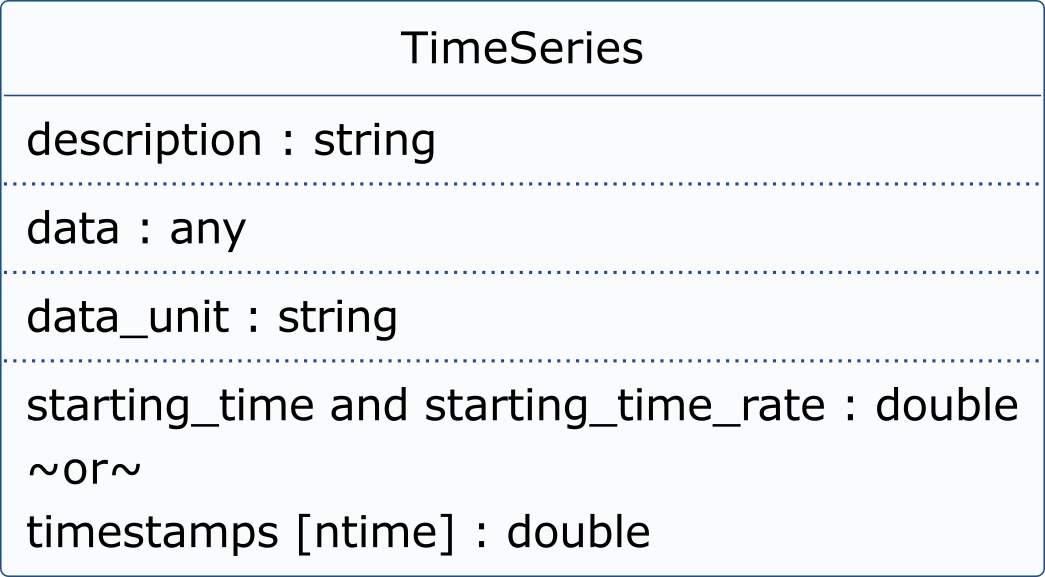    

### Regularly Sampled Data

While our mouse hunted cookie crumbs, an **indoor-positioning sensor** (IPS) streamed X/Y coordinates at 10 Hz for 30 s. We’ll store the resulting 2 × N matrix in a [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html) object.

% Synthetic 2-D trajectory  (helper returns a 2×300 array)
data = getRandomTrajectory();

time_series_with_rate = types.core.TimeSeries( ...
    'description', ['2D position of mouse in arena. The first column ', ...
        'represents x coordinates, the second column represents y coordinates'], ... % Optional
    'data', data, ...                               % Required
    'data_unit', 'meters', ...                      % Required
    'starting_time', 0.0, ...                       % Required
    'starting_time_rate', 10.0);                    % Required
disp(time_series_with_rate)

  TimeSeries with properties:

     starting_time_unit: 'seconds'
    timestamps_interval: 1
        timestamps_unit: 'seconds'
                   data: [2×300 double]
              data_unit: 'meters'
               comments: 'no comments'
                control: []
    control_description: ''
        data_continuity: ''
        data_conversion: 1
            data_offset: 0
        data_resolution: -1
            description: '2D position of mouse in arena. The first column represents x coordinates, the second column represents y coordinates'
          starting_time: 0
     starting_time_rate: 10
             timestamps: []



Next, we add the [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html) to the [`NWBFile`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/NWBFile.html) by inserting it into the file’s `acquisition` container. This container can hold any number of data objects—each stored as a name-value pair where the *name* is a user-defined name and the *value* is the data object itself:

nwb.acquisition.set('IPSTimeseries', time_series_with_rate);
% Confirm that the timeseries was added to the file
disp( size( nwb.acquisition.get('IPSTimeseries').data ) ) % Should show 2, 300

     2   300



### Irregularly Sampled Data

To save irregularly sampled data, we should replace the single `starting_time`` + ``rate` pair with an explicit vector of `timestamps`. Let's pretend that the IPS drops samples and has an irregular sampling rate:

[irregularData, timepoints] = getIrregularRandomTrajectory();
% Drop frame 120 to create a gap
irregularData(:,120) = []; timepoints(120) = [];

time_series_with_timestamps = types.core.TimeSeries( ...
    'description', 'XY position (irregular)', ...
    'data', irregularData, ...
    'data_unit', 'meters', ...
    'timestamps', timepoints);

% Add the TimeSeries to the NWB file
nwb.acquisition.set('IPSTimeseriesWithJitterAndMissingSamples', time_series_with_timestamps);

% Quick sanity check: are the first three Δt uneven?
disp(diff(time_series_with_timestamps.timestamps(1:4)))       % should NOT all be 0.1 s

    0.1259    0.0181    0.1624



**Key difference:** `timestamps` takes the place of `starting_time` and `starting_time_rate``. `Everything else—adding the series to `acquisition`, slicing, plotting—works exactly the same. 

With both a **rate-based **and an **irregular** `TimeSeries` in your file, you’ve now covered the two most common clocking scenarios you’ll meet in real experiments.

## Other Types of Time Series 

The [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html) class has a family of specialized subclasses—each adding or tweaking fields to suit a particular kind of data. One example is the [`AnnotationSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/AnnotationSeries.html) → plain-text labels tied to timestamps (cues, notes, rewards, etc.).

**Tip**: For a full overview of [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html) subtypes, please check out the [type hierarchy](https://nwb-schema.readthedocs.io/en/latest/format.html#type-hierarchy) in the NWB schema documentation.

A crumb dispenser *dings* at random times and drops different types of cookie crumbs. We’ll record the drop events in an [`AnnotationSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/AnnotationSeries.html) and store it under `stimulus_presentation`.

% Create an AnnotationSeries object with annotations for airpuff stimuli
annotations = types.core.AnnotationSeries( ...
    'description', 'Log time and flavour for cookie crumb drops', ...
    'data', {'Snickerdoodles', 'Chocolate Chip Cookies', 'Peanut Butter Cookies'}, ...
    'timestamps', [3.0, 12.0, 25.0] ...
);

% Add the AnnotationSeries to the NWBFile's stimulus group
nwb.stimulus_presentation.set('FoodDrops', annotations);

**What to remember**

- `AnnotationSeries` is still a `TimeSeries`, but `data` is **text**, not numbers.

- Put cue / reward / comment streams in `stimulus_presentation` (or another container that fits your experiment).

That’s it! You now have both continuous data (position) **and** discrete event markers logged in your NWB file. In the next section we’ll look at storing processed behavioral data such as the mouse’s X/Y path in arena coordinates.

## Add Behavioral Data

So far we’ve stored **raw, acquired** data—the IPS sensor’s 10 Hz position stream. Now suppose a lab-mate is testing her new video-based deep-learning tracker and hands you a *processed* XY path.

### SpatialSeries and Position

To store the processed XY path, we can use another subclass of the [`TimeSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeSeries.html): the [`SpatialSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/SpatialSeries.html). This class adds a `reference_frame` property that defines what the data coordinates are measured relative to. We will create the [`SpatialSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/SpatialSeries.html) and add it to a [`Position`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Position.html) object as a way to inform data analysis and visualization tools that this [`SpatialSeries`](https://pynwb.readthedocs.io/en/latest/pynwb.behavior.html#pynwb.behavior.SpatialSeries) object represents the position of the subject. 

The relationship of the three classes just mentioned is shown in the UML diagram below. For our purposes, all you need to know is that an open triangle means "extends" (i.e., is a specialized subtype of), and an open diamond means "is contained within" (Learn more about class diagrams on [the wikipedia page](https://en.wikipedia.org/wiki/Class_diagram)).

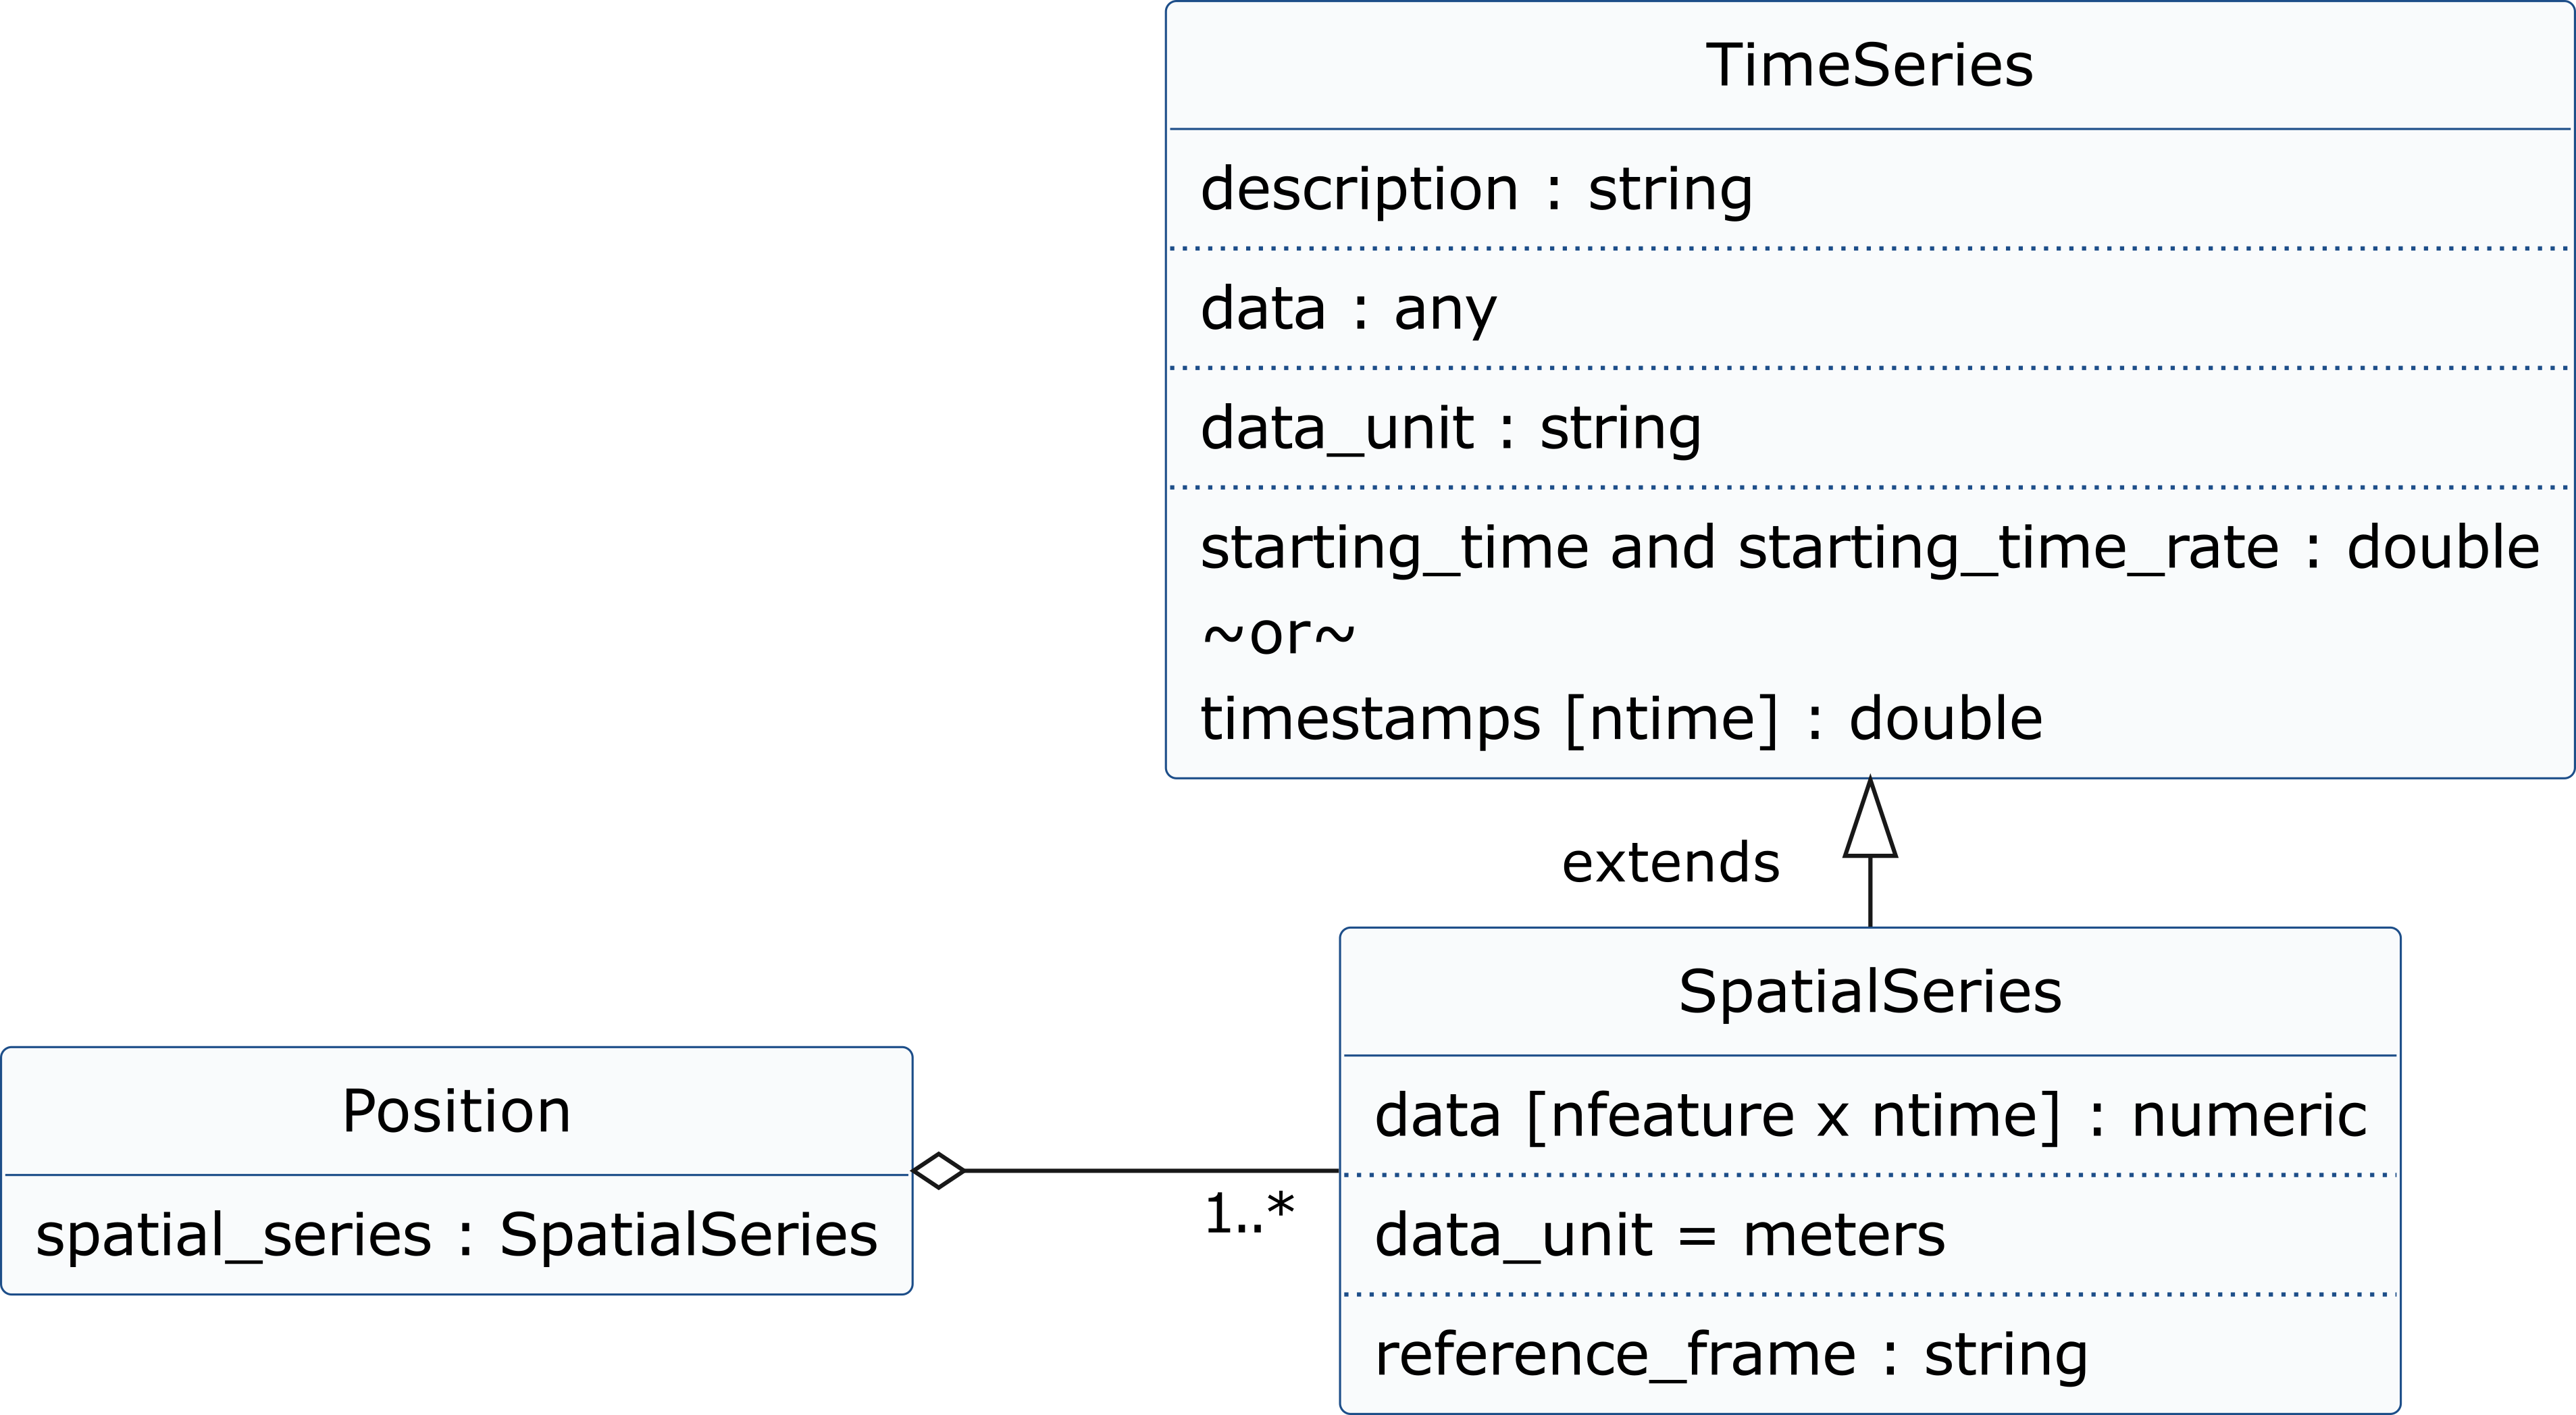

positionData = getVideoTrackerData();

% Create SpatialSeries object
spatial_series_ts = types.core.SpatialSeries( ...
    'data', positionData, ...
    'reference_frame', '(0,0) is bottom left corner of arena', ...
    'starting_time', 0, ...
    'starting_time_rate', 30 ...
);

% Create Position object and add SpatialSeries
position = types.core.Position('SpatialSeries', spatial_series_ts);

In NWB, results produced **after** the experiment belong in a **processing module**, separate from the immutable acquisition data. The difference is that the processed data could change later if the video-tracking software was improved, whereas the raw data is streamed directly from a sensor, and should never change. Because processed data can be very diverse, NWB allows us to create processing modules, which are like folders, to store related processed data or data that comes from a single algorithm. 

Create a processing module called "behavior" for storing behavioral data in the [`NWBFile`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/NWBFile.html) and add the [`Position`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Position.html) object to the module.

% Create processing module
behavior_module = types.core.ProcessingModule(...
    'description', 'Contains behavioral data');

% Add the Position object (that holds the SpatialSeries object) to the module 
% and name the Position object MousePosition
behavior_module.nwbdatainterface.set('MousePosition', position);

% Finally, add the processing module to the NWBFile object, and name the 
% processing module "behavior"
nwb.processing.set('behavior', behavior_module);

### Trials

Our experiment follows a trial structure where each trials lasts for 10 seconds, and we are recording how long it takes the mouse to find the cookie crumb. Trials are stored using the [`TimeIntervals`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeIntervals.html) type, a subclass of the [`DynamicTable`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/DynamicTable.html) type. [`DynamicTable`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/hdmf_common/DynamicTable.html) objects are used to store tabular metadata throughout NWB, and is often used for storing information about trials, electrodes, and sorted units. They offer flexibility for tabular data by allowing required columns, optional columns, and custom columns. The [`TimeIntervals`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/TimeIntervals.html) trials table can be thought of as a table with this structure:

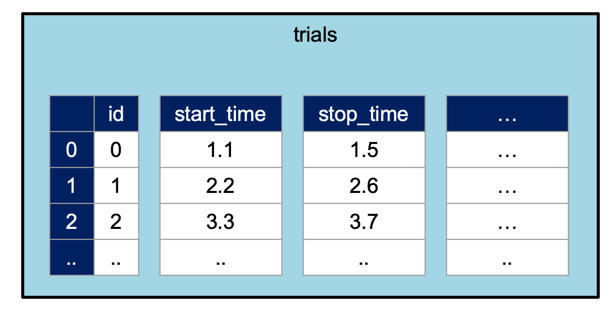

Here, we are adding two custom columns:

- `time_to_find` (float) - which will be the time it took out mouse to find the treats after the cookie ding was played.

- **was_found** (boolean) - whether cookie crumb was found on time.

trials = types.core.TimeIntervals( ...
    'colnames', {'start_time', 'stop_time', 'time_to_find', 'was_found'}, ...
    'description', 'trial data and properties');

trials.addRow('start_time', 0, 'stop_time', 10, 'time_to_find', 3.2, 'was_found', true)
trials.addRow('start_time', 10.0, 'stop_time', 20.0, 'time_to_find', 4.7, 'was_found', false)
trials.addRow('start_time', 20.0, 'stop_time', 30.0, 'time_to_find', 3.9, 'was_found', true)

trials.toTable() % visualize the table

ans = 3×5 table
    id    start_time    stop_time    time_to_find    was_found
    __    __________    _________    ____________    _________

    0          0           10            3.2           true   
    1         10           20            4.7           false  
    2         20           30            3.9           true   


When adding trials to the [`NWBFile`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/NWBFile.html) object, there are two ways to do it:

% Alternative A - There is only one trials table:
nwb.intervals_trials = trials;

% Alternative B - There are multiple trials tables, you will need to use custom names for
% each one:
nwb.intervals.set('CookieSearchTrials', trials);

For a more detailed tutorial on dynamic tables, see the [Dynamic tables](matlab:open('./dynamic_tables.mlx')) tutorial.

## Write

Now, to write the NWB file that we have built so far:

nwbExport(nwb, 'intro_tutorial.nwb')

We can use the [HDFView](https://www.hdfgroup.org/downloads/hdfview/) application to inspect the resulting NWB file.

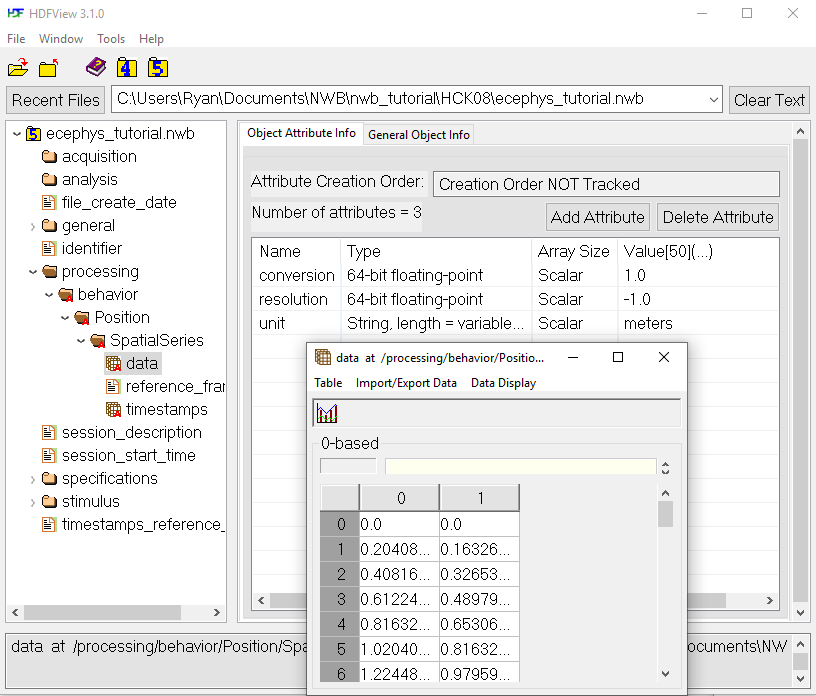

## Read

We can also read the file back using MatNWB and inspect its contents. 

read_nwbfile = nwbRead('intro_tutorial.nwb', 'ignorecache')

read_nwbfile =   NwbFile with properties:

                                             nwb_version: '2.9.0'
                                        file_create_date: [1×1 types.untyped.DataStub]
                                              identifier: 'MyLab_20250411_1530_AL'
                                     session_description: 'Mouse searching for cookie crumbs in an open arena'
                                      session_start_time: [1×1 types.untyped.DataStub]
                               timestamps_reference_time: [1×1 types.untyped.DataStub]
                                             acquisition: [2×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: ''
                                         general_devices: [0×1 ty

We can print the [`SpatialSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/SpatialSeries.html) data traversing the hierarchy of objects. The processing module called `'behavior'` contains our [`Position`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Position.html) object named `'MousePosition'`. The [`Position`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/Position.html) object contains our [`SpatialSeries`](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/SpatialSeries.html) object named `'SpatialSeries'`.

read_spatial_series = read_nwbfile.processing.get('behavior'). ...
    nwbdatainterface.get('MousePosition').spatialseries.get('SpatialSeries')

read_spatial_series =   SpatialSeries with properties:

        reference_frame: '(0,0) is bottom left corner of arena'
     starting_time_unit: 'seconds'
    timestamps_interval: 1
        timestamps_unit: 'seconds'
                   data: [1×1 types.untyped.DataStub]
              data_unit: 'meters'
               comments: 'no comments'
                control: []
    control_description: ''
        data_continuity: ''
        data_conversion: 1
            data_offset: 0
        data_resolution: -1
            description: 'no description'
          starting_time: 0
     starting_time_rate: 30
             timestamps: []


### Loading Data

Counter to normal MATLAB workflow, data arrays are read passively from the file. Calling `read_spatial_series.data` does not read the data values, but presents a `DataStub` object that can be indexed to read data. 

read_spatial_series.data

ans =   DataStub with properties:

    filename: 'intro_tutorial.nwb'
        path: '/processing/behavior/MousePosition/SpatialSeries/data'
        dims: [2 900]
       ndims: 2
    dataType: 'double'


This allows you to conveniently work with datasets that are too large to fit in RAM all at once. Access all the data in the matrix using the `load` method with no arguments. 

read_spatial_series.data.load()

ans =    -0.0108   -0.0043    0.0022    0.0087    0.0022   -0.0045   -0.0111   -0.0197   -0.0283   -0.0369   -0.0360   -0.0348   -0.0336   -0.0374   -0.0413   -0.0453   -0.0337   -0.0216   -0.0096   -0.0162   -0.0236   -0.0309   -0.0312   -0.0311   -0.0310   -0.0352   -0.0396   -0.0440   -0.0468   -0.0495   -0.0522   -0.0542   -0.0561   -0.0580   -0.0519   -0.0453   -0.0386   -0.0375   -0.0369   -0.0363   -0.0492   -0.0634   -0.0776   -0.0847   -0.0911   -0.0975   -0.0833   -0.0668   -0.0503   -0.0436
    0.0173    0.0196    0.0218    0.0241    0.0206    0.0172    0.0137    0.0196    0.0258    0.0319    0.0369    0.0419    0.0469    0.0590    0.0713    0.0836    0.0832    0.0823    0.0815    0.0771    0.0726    0.0681    0.0675    0.0671    0.0667    0.0686    0.0706    0.0727    0.0648    0.0563    0.0477    0.0468    0.0463    0.0459    0.0409    0.0356    0.0303    0.0315    0.0333    0.0352    0.0378    0.0405    0.0431    0.0414    0.0393    0.0371    0.0461    0.0563    0.0666   

If you only need a section of the data, you can read only that section by indexing the `DataStub` object like a normal array in MATLAB. This will just read the selected region from disk into RAM. This technique is particularly useful if you are dealing with a large dataset that is too big to fit entirely into your available RAM.

read_spatial_series.data(:, 1:10)

ans =    -0.0108   -0.0043    0.0022    0.0087    0.0022   -0.0045   -0.0111   -0.0197   -0.0283   -0.0369
    0.0173    0.0196    0.0218    0.0241    0.0206    0.0172    0.0137    0.0196    0.0258    0.0319


## Next Steps

This concludes the introductory tutorial. Please proceed to one of the specialized tutorials, which are designed to succeed this one.

- [Extracellular electrophysiology](matlab:open('./ecephys.mlx'))

- [Intracellular electrophysiology](matlab:open('./icephys.mlx'))

- [Optical physiology](matlab:open('./ophys.mlx'))

Refer to the [API documentation](https://matnwb.readthedocs.io/en/latest/pages/neurodata_types/core/index.html) to learn what data types are available.

## Local Functions

function result = getRandomTrajectory()
    samplingRate        = 10;                       % 10 Hz sampling
    experimentDuration  = 30; 
    t = 0 : 1/samplingRate : experimentDuration;    % continuous timeline
    t = t(1:300);

    % random walk in metres
    rng(42);
    step      = 0.02 * randn(2, numel(t));
    result    = cumsum(step,2);

    rng('default')
end

function [data, timepoints] = getIrregularRandomTrajectory()
    data = getRandomTrajectory();
    samplingRate = 10;                                          % 10 Hz sampling    
    jitter = 0.02 * randn(1, size(data, 2));                    % ±20 ms
    timepoints = (0:size(data, 2) - 1) / samplingRate + jitter; % Irregular sampling
end

function result = getVideoTrackerData()
    % Get some 2D trajectory
    data = getRandomTrajectory();

    % Number of original points
    n = length(data);

    % Define original and new sample positions
    xOriginal = 1:n;
    xNew = linspace(1, n, n*3);

    % Preallocate result
    result = zeros(2, numel(xNew));

    % Interpolate each row separately
    result(1,:) = interp1(xOriginal, data(1,:), xNew, 'linear');
    result(2,:) = interp1(xOriginal, data(2,:), xNew, 'linear');
end
